# Semedo Test Script

In this live script, we test aspects of the outputs/inputs to our pipeline that lead to reduced rank regression and factor analysis. Namely, before we can trust anything, we have to test minimally:

## Table of contents

### 0. Visualize trial windows slicing of$H$

Just to sanity check how we're cutting windows on H. You'll at some point need plots of this for illustration for this project.

 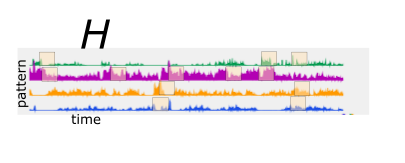

### I. Spike matrices sane

- Cells cofire -- but not all at once or not at all

- Rates/Counts look sanen (histogram of rates of counts)

- Some consistentcy across trials would be nice, but maybe not required .. could use the `spikeRateTensor` for this

### II. Event matrices sane

- LFP power it’s derived from plots well against raw LFP (JS15eeg01*.mat)

- Ripples power tend to avoid theta power (in ephys of JS15spectralBehavior.mat)

- Theta has positive speed correlation (in behavior of JS15spectralBehavior)

- Delta and ripples have negative speed correlation (in behavior of JS15spectralBehavior)

- Ripple power matches ACTUAL ripple times (in JS15ripples01.mat)

### III.  sane (in Reduced Rank Regression)

- imagesc of `_B`

### IV. Factors in $Q$ sane (in Factor Analysis)

load("Megatable.mat");


key = "326c076"

key = "326c076"

queryresult = [];

% buggy: repeating asking for inputs
% query the table
numToExamine = size(TABLE,1);
for i = 1:numToExamine
    fileTable = table2array(TABLE(i,"Filetable"));
    if fileTable.hash == key
        queryresult = TABLE(i,:);
    end
end

if isempty(queryresult)
    warning("the key does not exist");
end

Options = table2array(queryresult(1,"Optiontable"));
animal = table2array(Options (1,"animal"));

% if loaded checkpoint.mat
addpath(genpath("data" + filesep + animal)); % genpath enumerates every folder in inside the folder it's given
addpath(genpath('utils')); % all folders in utils added, including semedo code

## Testing

### I. Spike matrices $X_{hpc$ $X_{pfc}$ sane

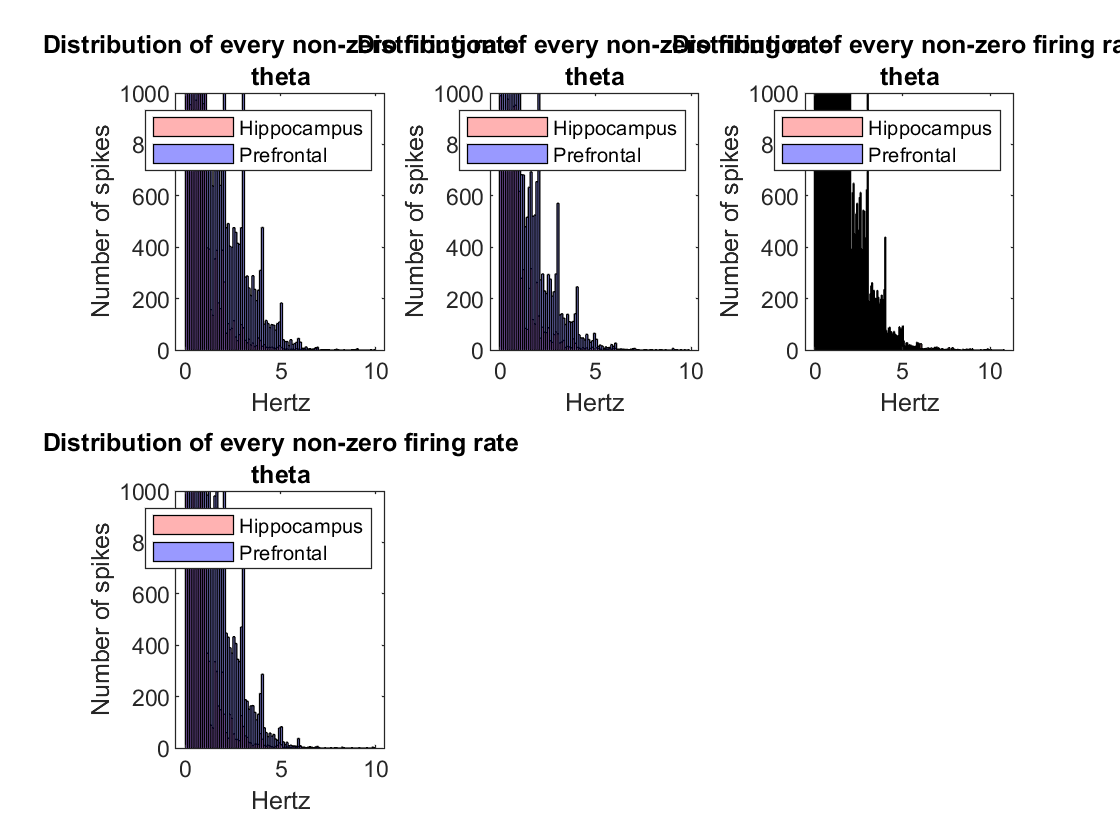

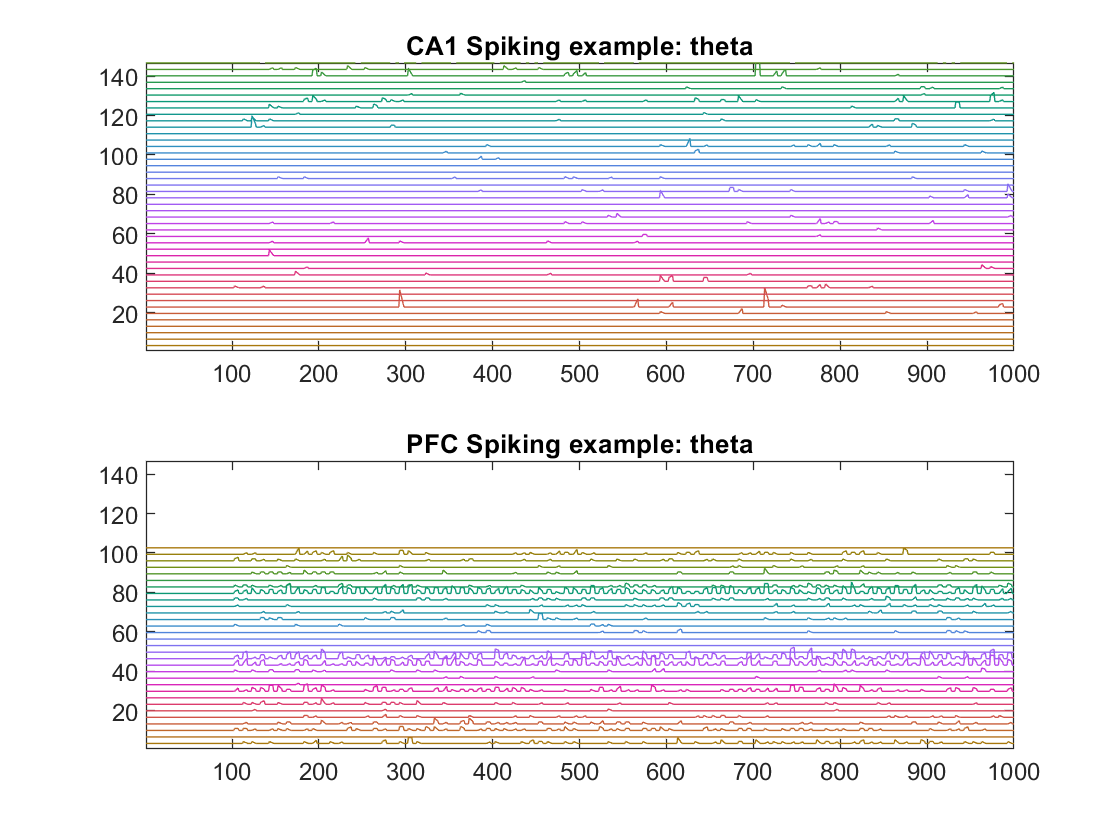

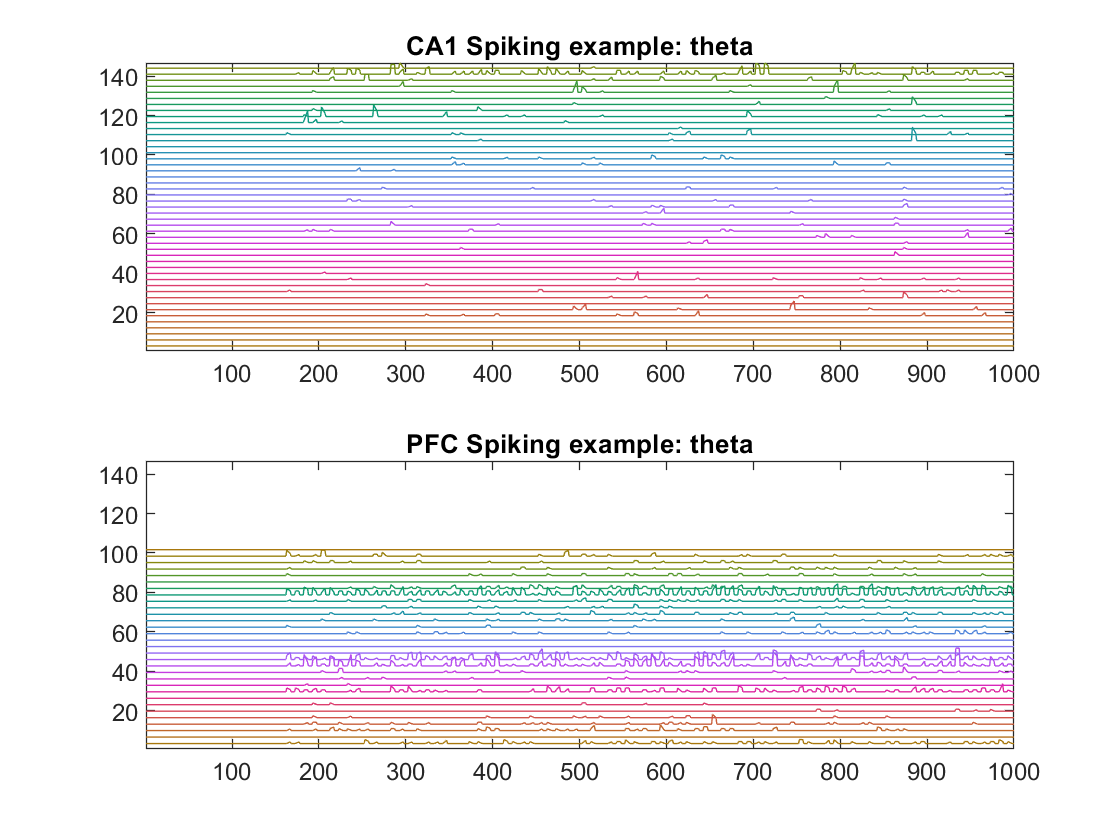

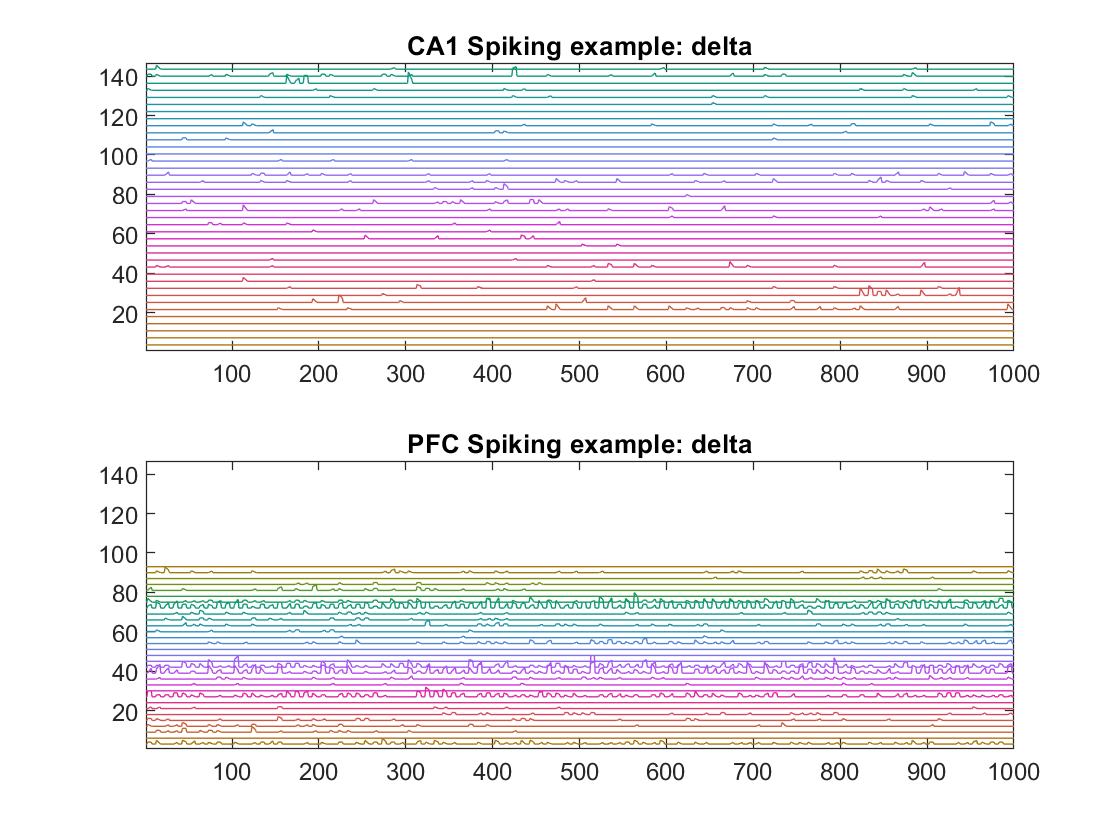

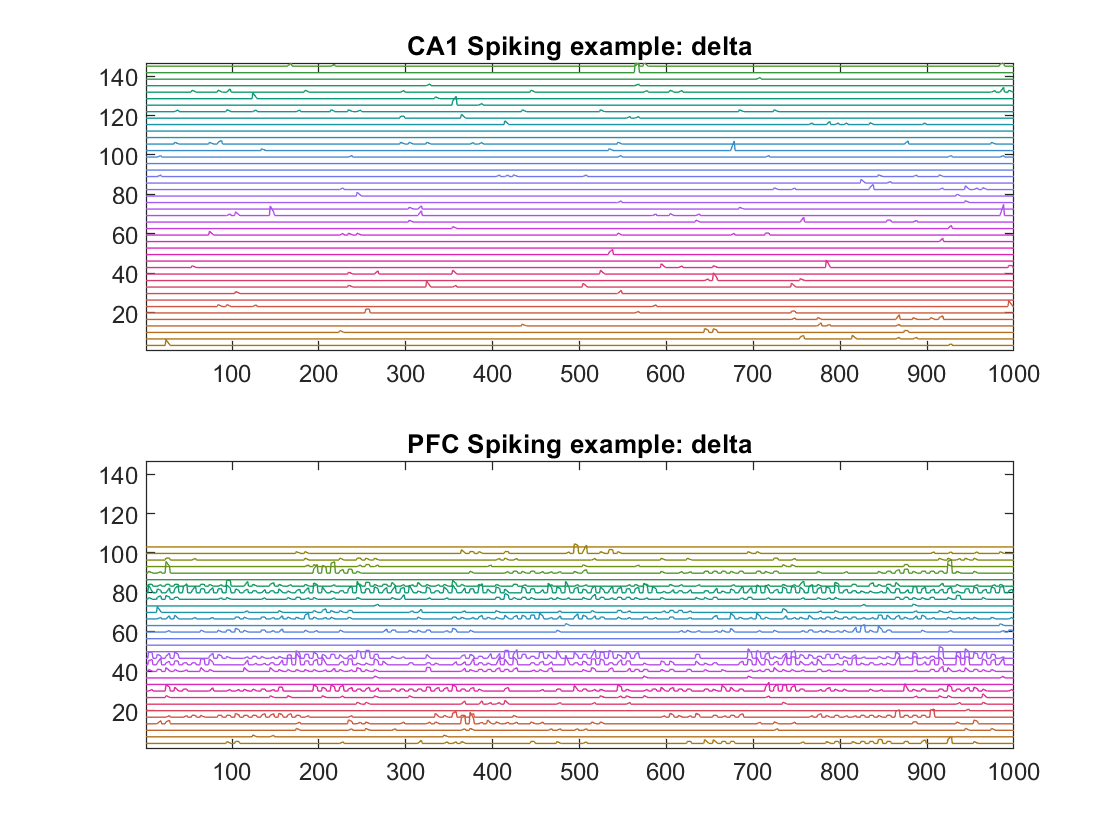

addpath('utils\cmocean')
for i = 1:numResult
    % What kind of firing rates do X_hpc and X_pfc take on?
    figure(80);
    if i == 1; clf; end
    curr_pfc = X_pfc{i};
    curr_hpc = X_hpc{i};
    subplot(2,3,i);
    hist_hpc = histogram(curr_hpc(curr_hpc ~= 0),'FaceColor','red', 'FaceAlpha',0.3);
    hold on;
    hist_pfc = histogram(curr_pfc(curr_pfc ~= 0),'FaceColor','blue', 'FaceAlpha',0.4);
    legend([hist_hpc, hist_pfc],'Hippocampus','Prefrontal')
    title(['Distribution of every non-zero firing rate' Patterns(i).name] )
    xlabel('Hertz')
    ylabel('Number of spikes')
    ylim([0,1000])
    %Do cells cofire? Let's just plot a curves for cell firing
    figure(100+i);clf
    subplot(2,1,1)
    % HPC
    [nHPC,ntrialTime] = size(curr_hpc);
    colorsPerNeuron = cmocean('phase', nHPC); % For the plot function we have to explicitly make a matrix of nNeurons x 3 (RGB), one color per neuron. colormap without the number only works with imagesc() or other types of heatmap.
    maxFiringRate = max(curr_hpc,[],"all"); % the "all" says to get max over all dimensions. same as max(max(X))
    for iNeuron = 1:nHPC
        column = X_hpc{i}(iNeuron,:);
        plot(column + iNeuron*maxFiringRate/3, 'color', colorsPerNeuron(iNeuron,:))
        hold on
    end
    xlim([1,1000])
    ylim([1,440/3])
    title("CA1 Spiking example: " + Patterns(1,i).name);
    
    ax=subplot(2,1,2);
    % PFC
    [nPFC,ntrialTime] = size(curr_pfc);
    colorsPerNeuron = cmocean('phase', nPFC); % For the plot function we have to explicitly make a matrix of nNeurons x 3 (RGB), one color per neuron. colormap without the number only works with imagesc() or other types of heatmap.
    maxFiringRate = max(curr_pfc,[],"all"); % the "all" says to get max over all dimensions. same as max(max(X))
    for iNeuron = 1:nPFC
        column = X_pfc{i}(iNeuron,:);
        plot(column + iNeuron*maxFiringRate/3, 'color', colorsPerNeuron(iNeuron,:))
        hold on
    end
    xlim([1,1000])
    ylim([1,440/3])
    title(ax,"PFC Spiking example: " + Patterns(1,i).name);
end

Looking at that in a different avenue, video frames of that activity. Here we just plot the same thing that we did previously, but windows of 1000 time points at a time for 1500 steps. (Run this in your command window if you want a live video. Do not resize while running it or the next part fails.)

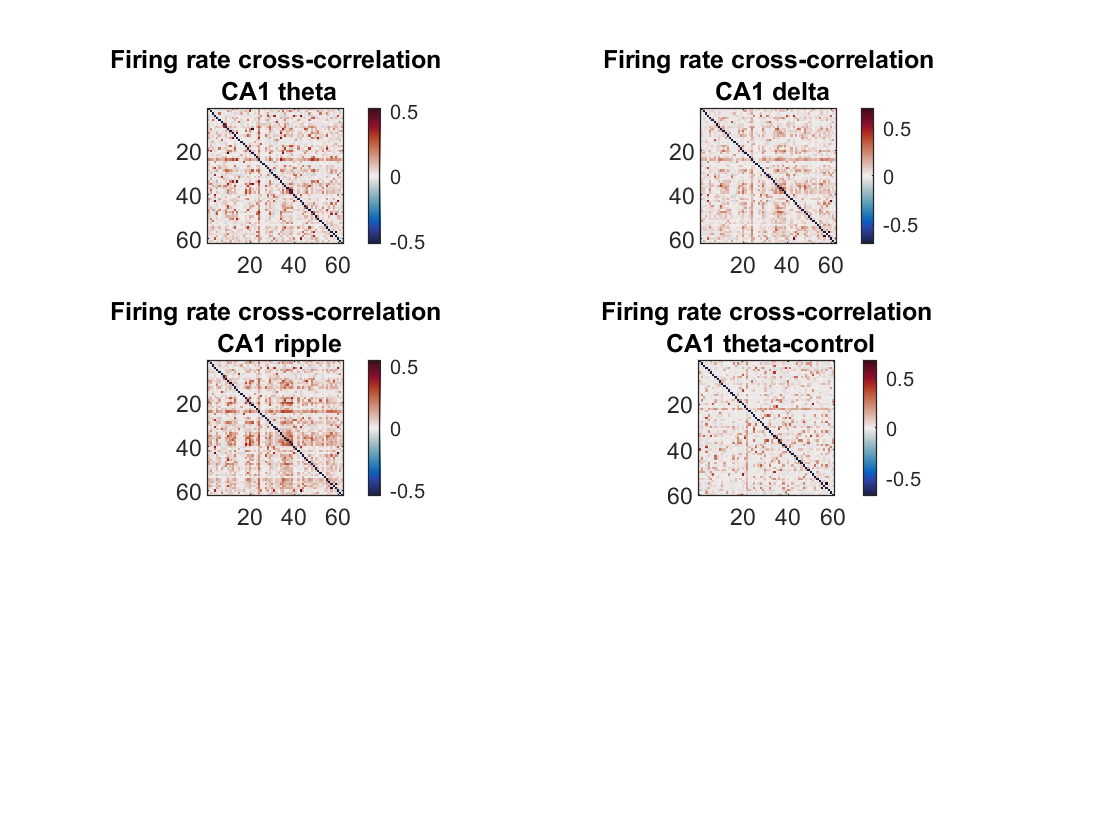

set(0,'DefaultFigureWindowStyle','docked')
tic % start a timer to later tell us how long this took ...
fig=figure('Position',[1 1 800 600]);
ax=gca;
%cla(ax);
frames = cell(1500,1); % storage to take frames of each figure plotted for the movie
szframeOfPlotting= cell(1500,1); % Size of every video frame snapshotted
disp('')
winSize=100;
subplot(2,1,1)
maxFiringRate = max(X_hpc{1},[],"all");
for t = 1:1500 % walk along for 1500 time steps
    %cla(ax)
    % Plot each neuron
    for iNeuron = 1:nHPC
        column = X_hpc(iNeuron,t:t+winSize-1);
        plot(ax, 1:winSize, column + iNeuron*(maxFiringRate/3), 'color', colorsPerNeuron(iNeuron,:),'linewidth',1.1)
        hold on

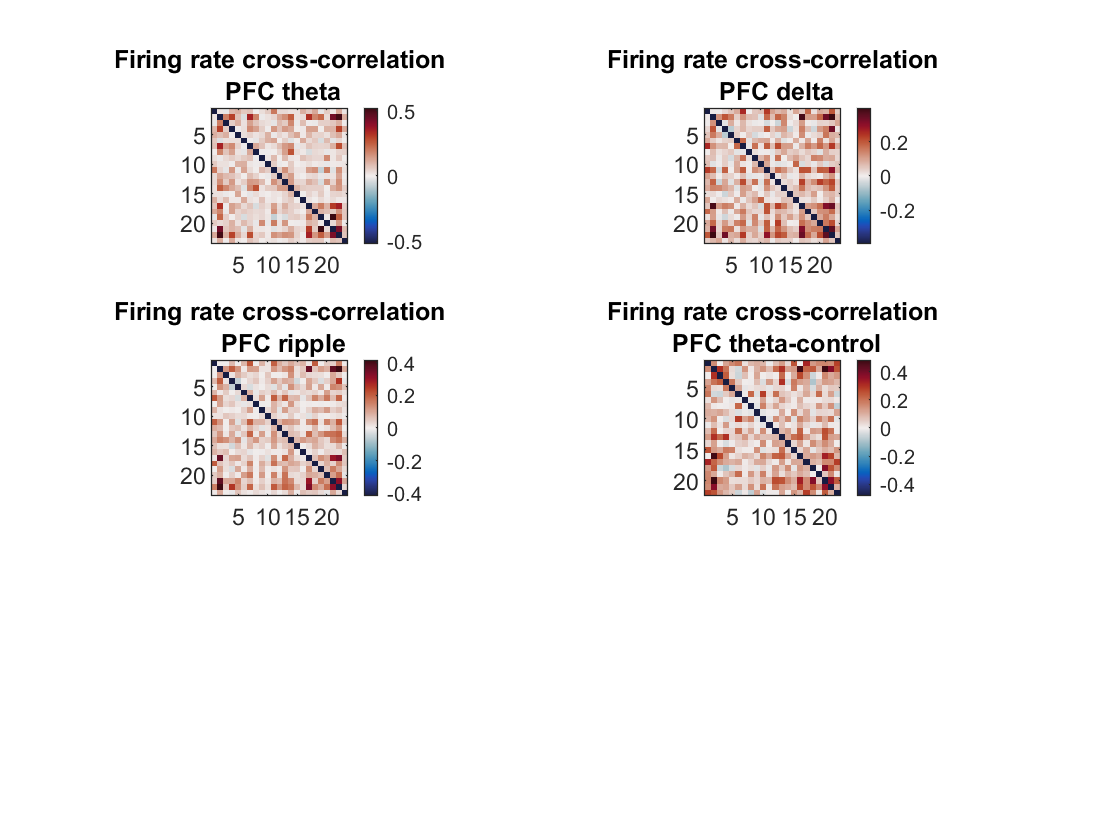

    end
    % Limit the window to the data
    xlim(ax,[1,winSize])
    ylim(ax,[1,550/3])
    % Store the frame
    frames{t} = getframe(ax);
    szframeOfPlotting{t} = size(frames{t}.cdata);
end
toc % tell us how long this took

And then cast  them into a video mp4 (assuming you didn't resize the window while plotting).

hist_pp =   Histogram with properties:

             Data: [1×1152 double]
           Values: [2 4 10 16 70 64 130 106 122 70 106 84 62 34 36 28 16 14 8 8 2 4 2 6 2 2 4]
          NumBins: 27
         BinEdges: [-0.0700 -0.0600 -0.0500 -0.0400 -0.0300 -0.0200 -0.0100 0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000]
         BinWidth: 0.0100
        BinLimits: [-0.0700 0.2000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


hist_hh =   Histogram with properties:

             Data: [1×8450 double]
           Values: [2 0 0 0 0 0 0 0 4 4 2 2 2 4 22 78 198 500 852 998 916 650 508 480 424 352 284 244 194 184 110 72 76 74 44 26 26 18 12 14 14 10 2 6 6 4 4 0 2 0 0 4 6 2 0 0 0 0 0 0 2 2]
          NumBins: 62
         BinEdges: [1×63 double]
         BinWidth: 0.0050
        BinLimits: [-0.1050 0.2050]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


cutoff_hpc = 0.0537

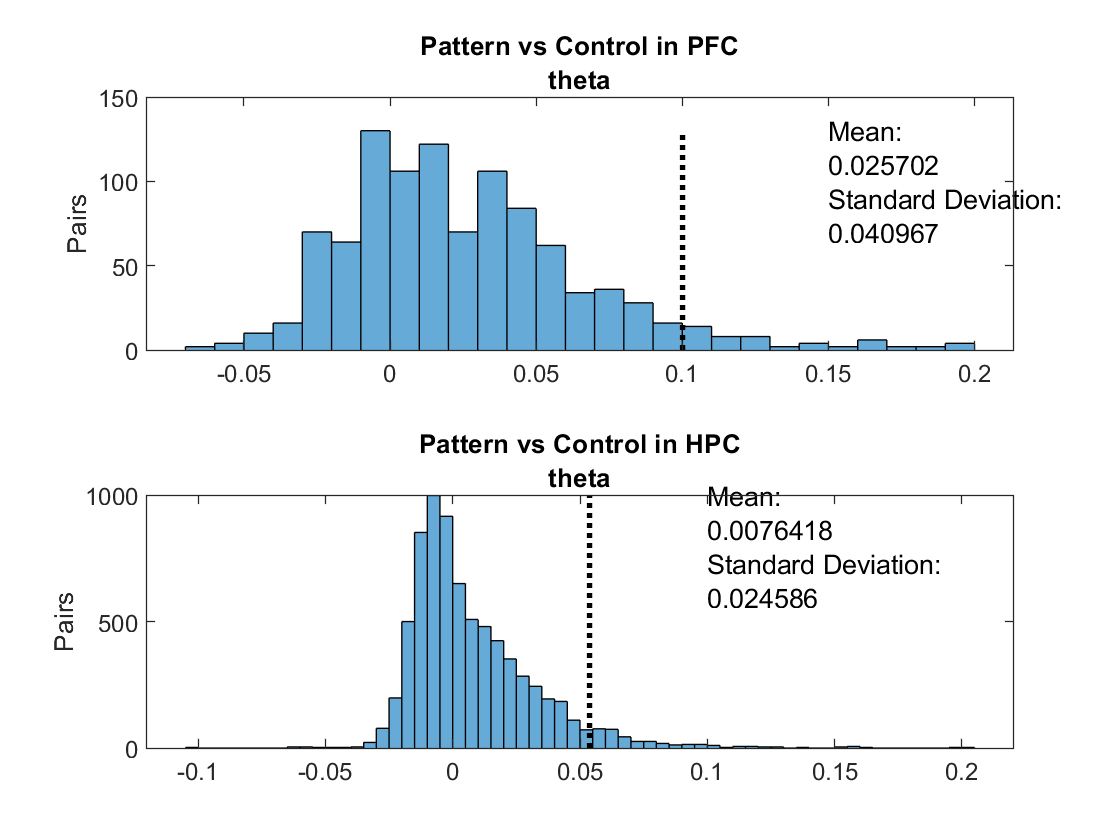

Index exceeds the number of array elements (4).

v = VideoWriter('~/spikingVideo.mp4',"MPEG-4"); % Setup a VideoWriter object
v.FrameRate = 15; % Set a property: Frame rate of video
v.open(); % open it
for frame = frames' % iterate over the frames we plotted
    frame = frame{1};
    v.writeVideo(frame) % write them into the mp4
end
v.close() % close the file
disp('done')

There will for sure be other ways to verify sanity of spiking. This is a good start.

### Cross-correlation between cells

figure

for p = 1:numel(X_hpc)
    subplot(3,2,p)
    [currPattern,allzerosHPC] = clean.throwOutAllZeros(X_hpc{p}');
    d_hpc = corrcoef(currPattern);
    
    for i = 1:size(d_hpc,1)
        d_hpc(i,i) = nan;
    end

velocity_correlations =     1.0000    0.3913   -0.1461       NaN
    0.3913    1.0000   -0.0431       NaN
   -0.1461   -0.0431    1.0000       NaN
       NaN       NaN       NaN       NaN


    imagesc(d_hpc)
    axis square
    colorbar
    title(sprintf("Firing rate cross-correlation\n CA1 ") + Patterns(1,p).name)
    cmocean('balance')
    set(gca,'clim',[-max(abs(d_hpc(:))), max(abs(d_hpc(:)))])
    
end

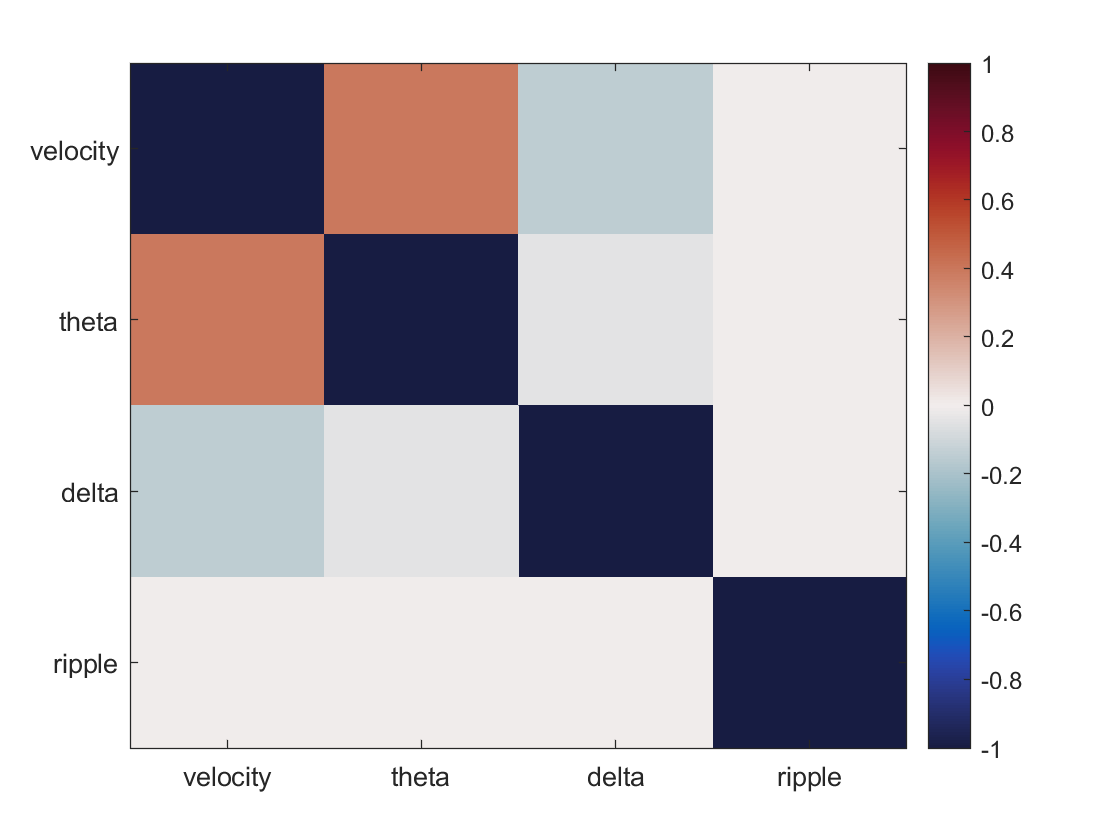

figure
for p = 1:numel(X_pfc)
    subplot(3,2,p)

    currPattern = clean.throwOutAllZeros(X_pfc{p}');
    d_pfc = corrcoef(currPattern);
    for i = 1:size(d_pfc,1)
        d_pfc(i,i) = nan;
    end
    imagesc(d_pfc)
    axis square
    colorbar
    title(sprintf("Firing rate cross-correlation\n PFC ") + Patterns(1,p).name)
    cmocean('balance')
    set(gca,'clim',[-max(abs(d_pfc(:))), max(abs(d_pfc(:)))])
end

#### Control is uncorrelated with pattern type

black line showing the 95% cutoff of correlation distributions.

This shows that the control pattern firing is uncorrelated with the specific firing pattern, allowing us to

reduce the control patterns to just one. 

Number unique periods = 17


Plotting epoch 1 rip:  000%  |                                    | 0/10336 [00:00:00<Inf:NaN:NaN, Inf it/s]

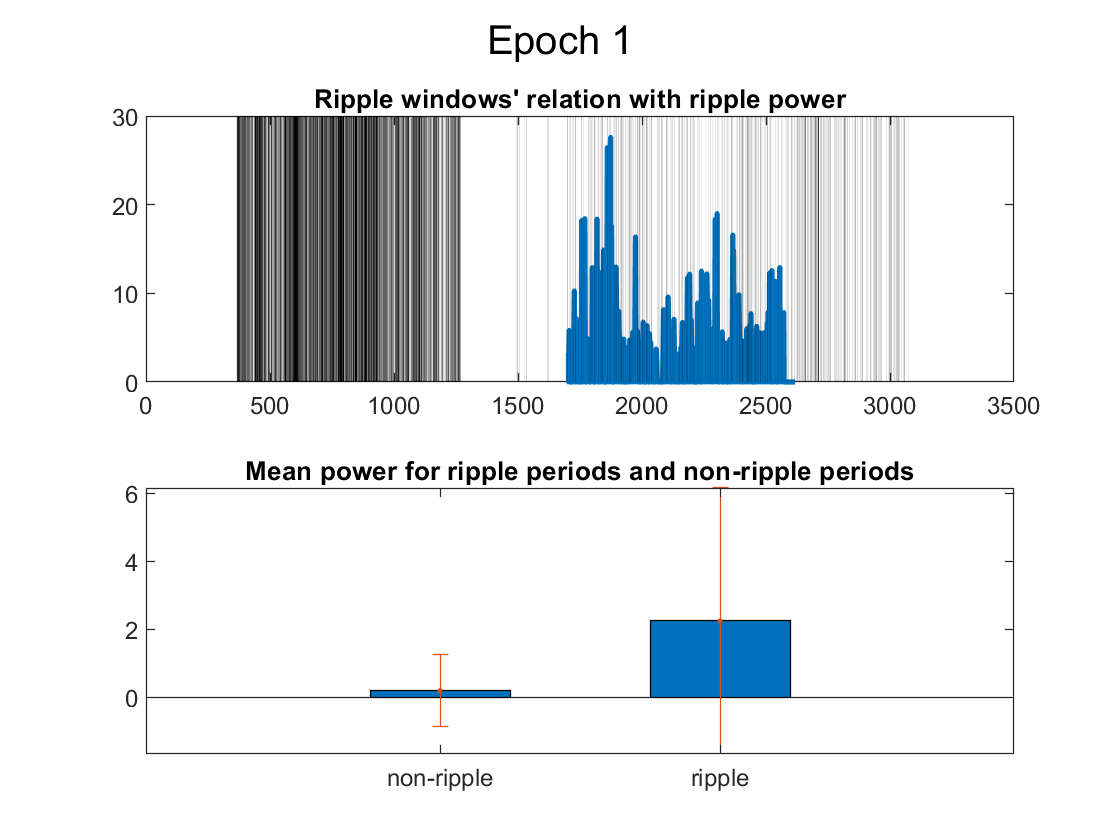

Plotting epoch 2 rip:  000%  |                                      | 0/3980 [00:00:00<Inf:NaN:NaN, Inf it/s]

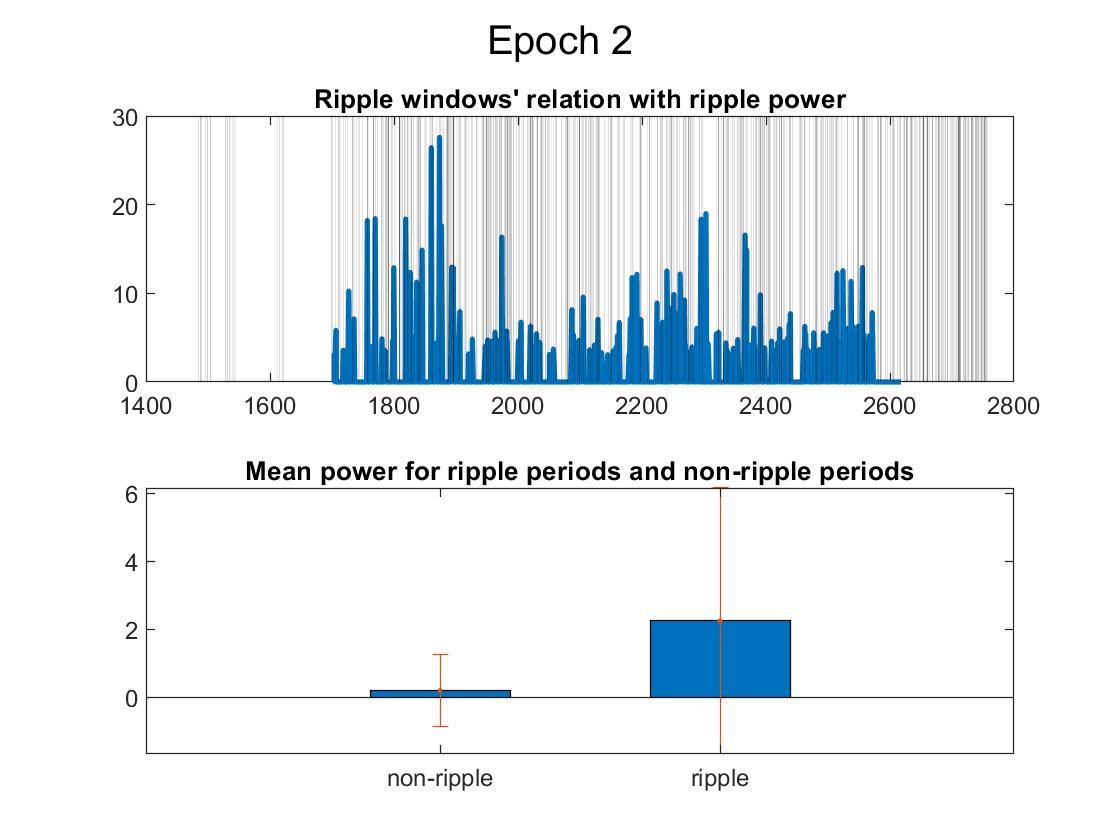

Plotting epoch 4 rip:  000%  |                                      | 0/3693 [00:00:00<Inf:NaN:NaN, Inf it/s]

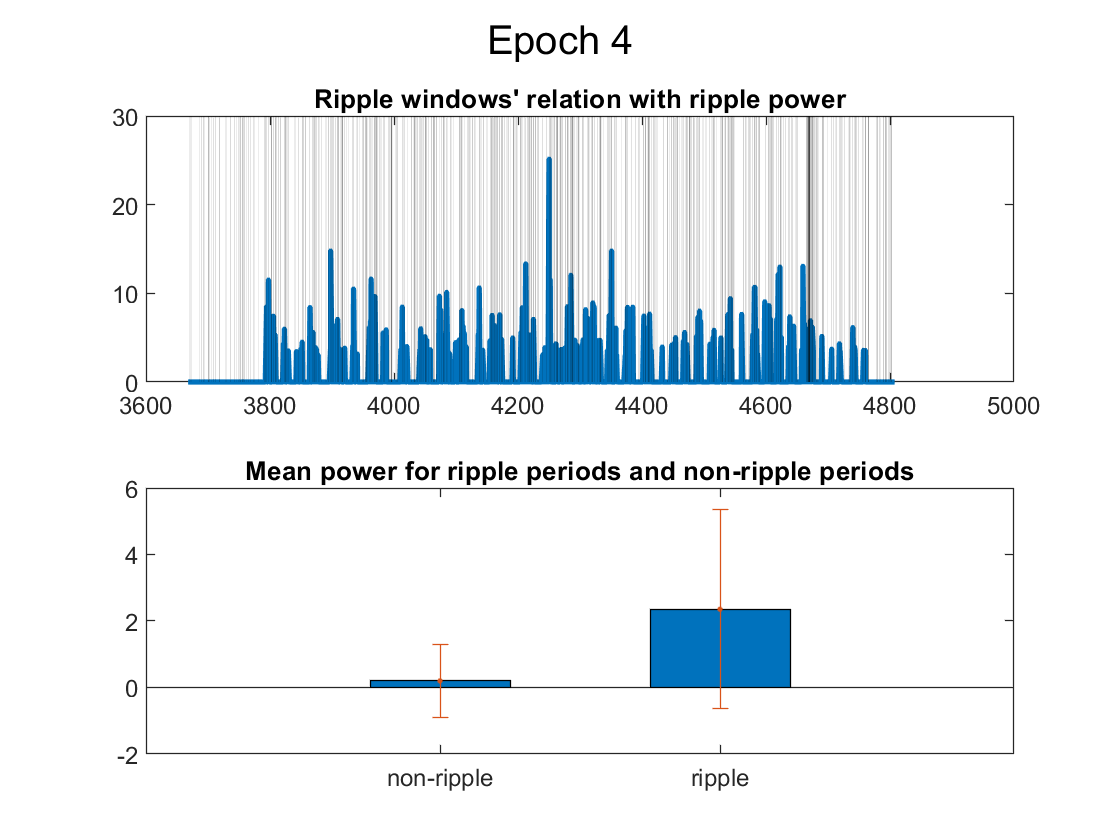

Plotting epoch 6 rip:  000%  |                                      | 0/3361 [00:00:00<Inf:NaN:NaN, Inf it/s]

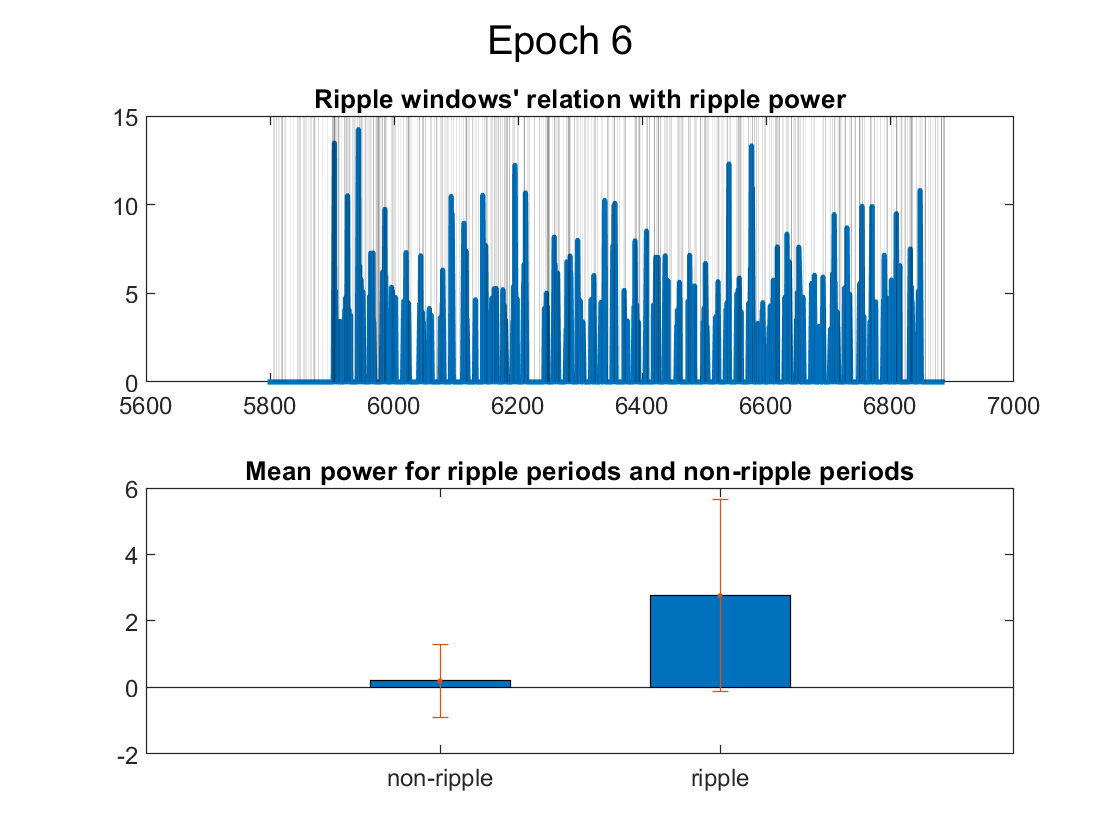

Plotting epoch 8 rip:  000%  |                                      | 0/3212 [00:00:00<Inf:NaN:NaN, Inf it/s]

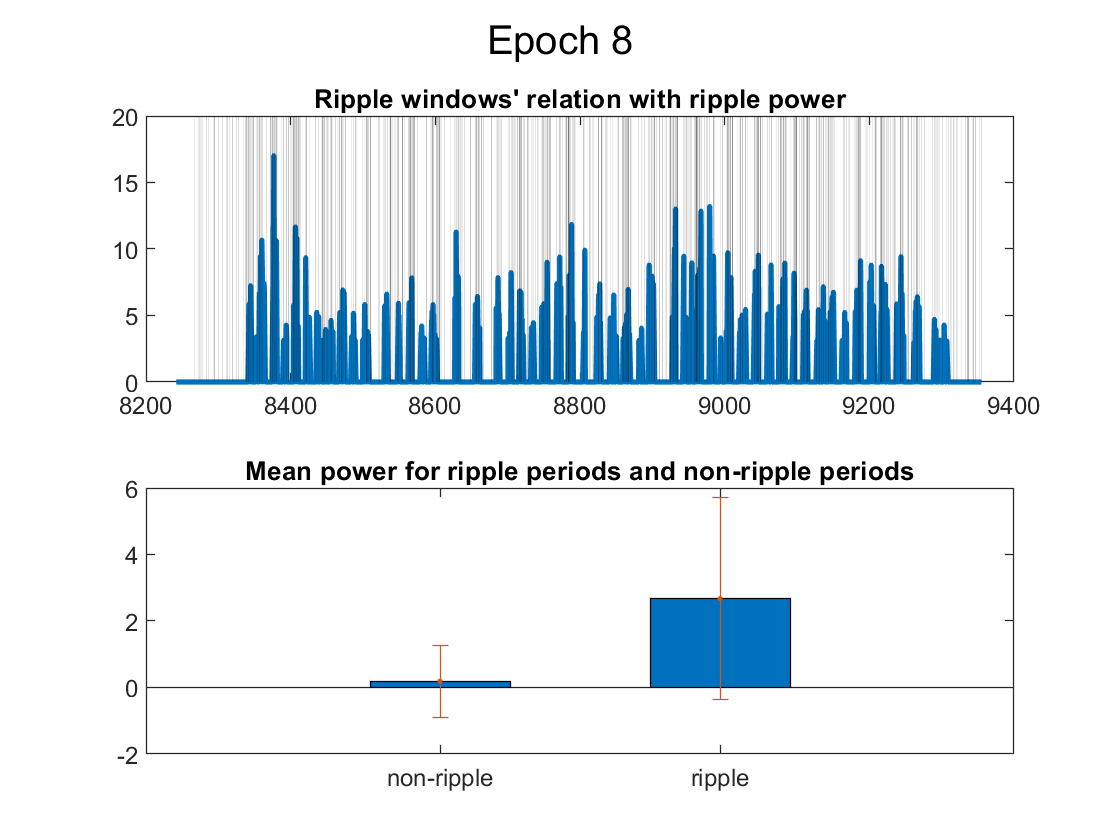

Plotting epoch 10 ri:  000%  |                                      | 0/2617 [00:00:00<Inf:NaN:NaN, Inf it/s]

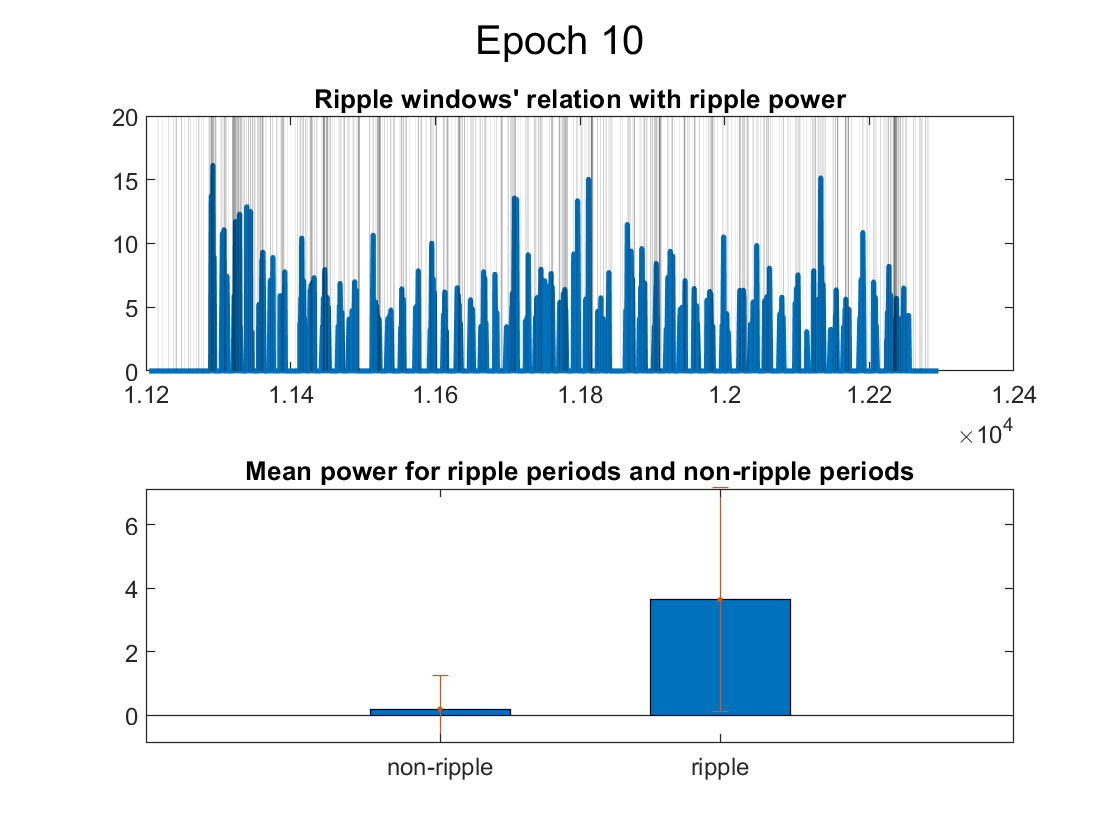

Plotting epoch 12 ri:  000%  |                                      | 0/2874 [00:00:00<Inf:NaN:NaN, Inf it/s]

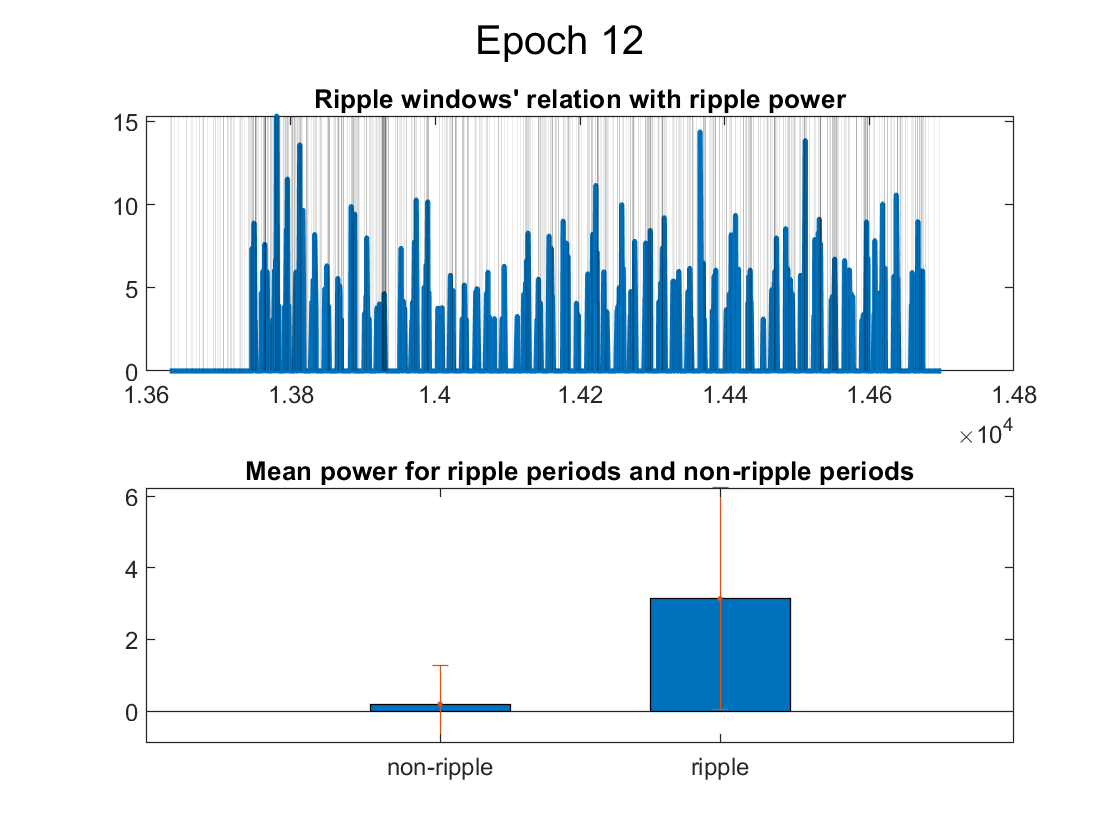

Plotting epoch 14 ri:  000%  |                                      | 0/2625 [00:00:00<Inf:NaN:NaN, Inf it/s]

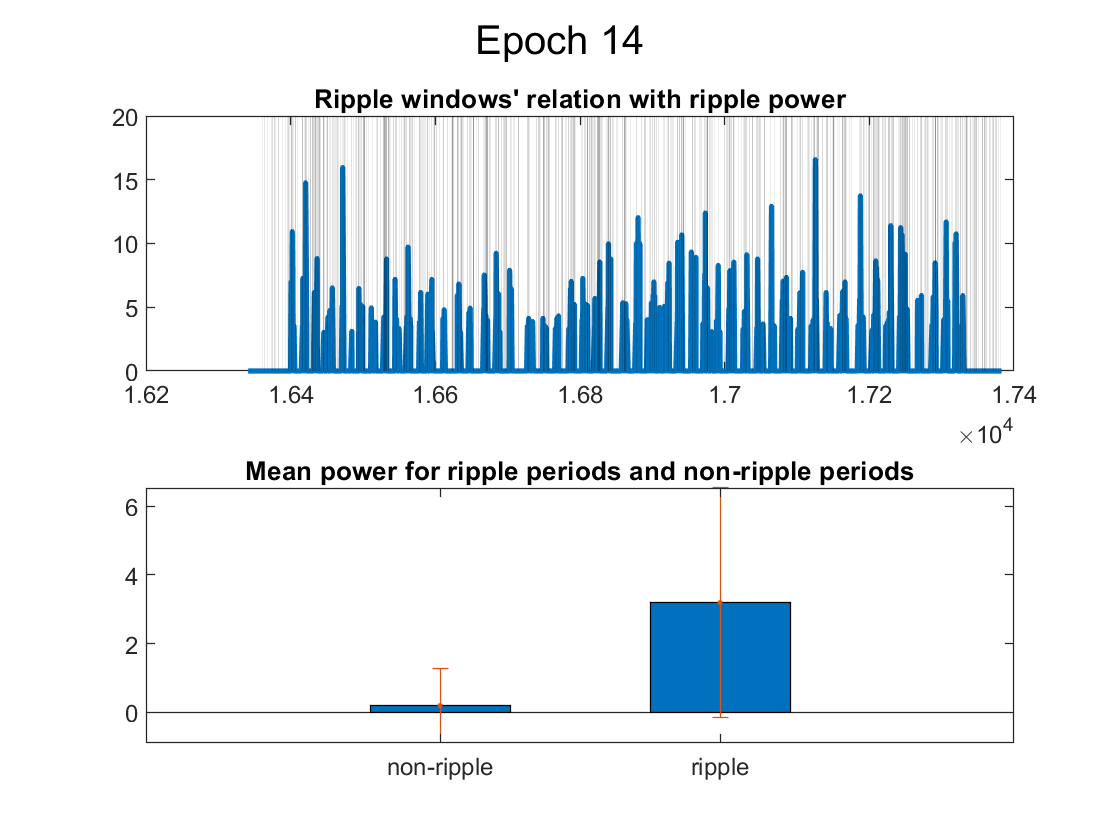

Plotting epoch 16 ri:  000%  |                                      | 0/2392 [00:00:00<Inf:NaN:NaN, Inf it/s]

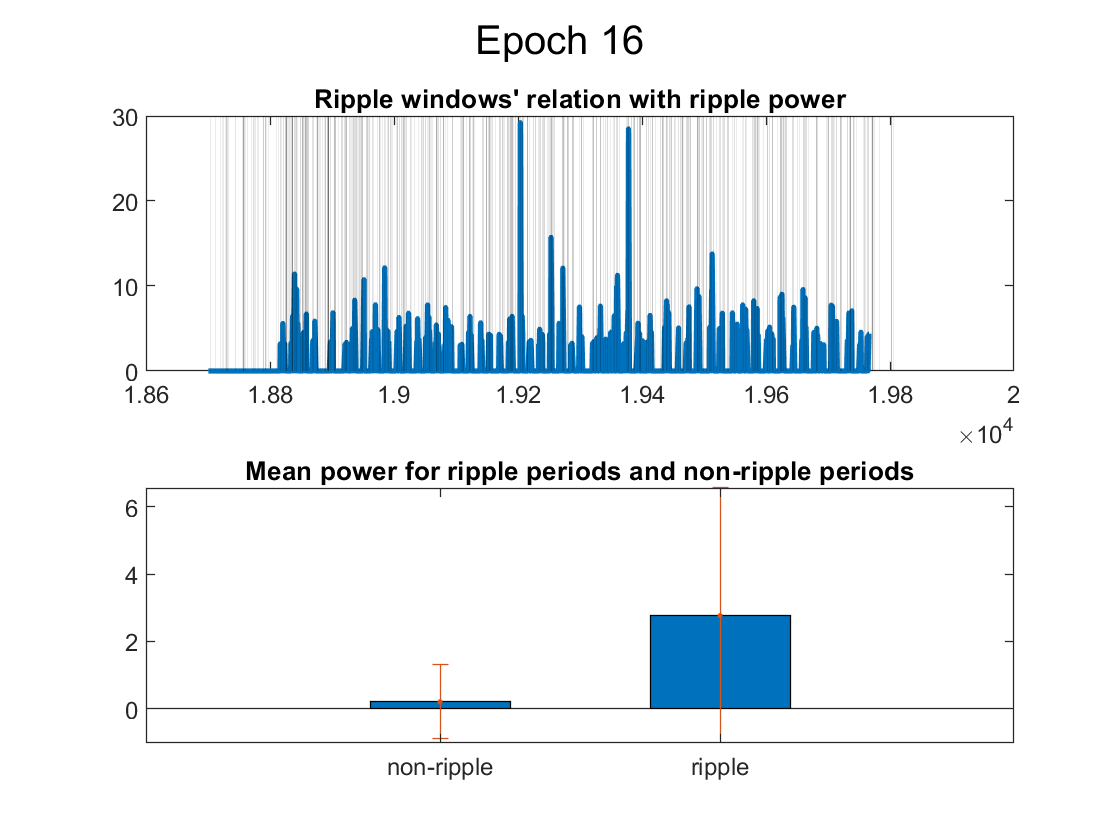

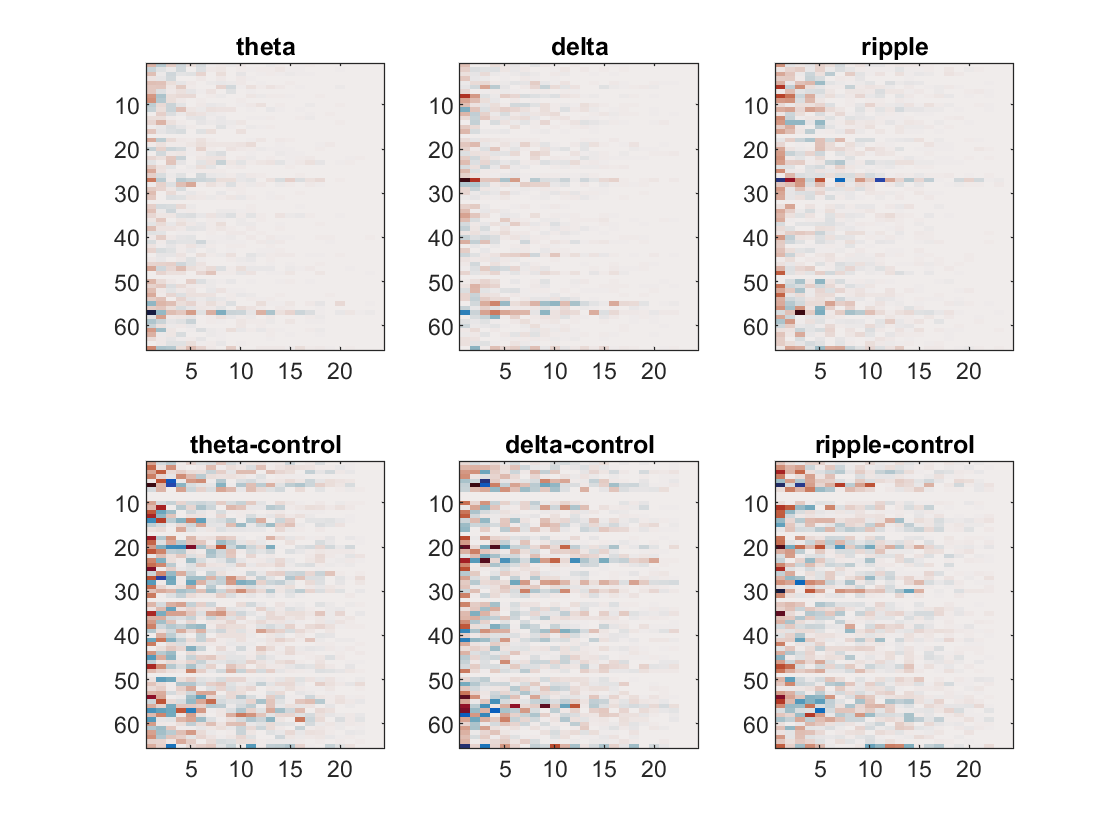

% if Option.singleControl == true
%     disp ("already checked")
% else
for i = 1:nPatterns
    curr_hpcPattern = X_hpc{i}';
    curr_pfcPattern = X_pfc{i}';
    
    curr_hpcControl = X_hpc{nPatterns+i}';
    curr_pfcControl = X_pfc{nPatterns+i}';
    
    linearized_hpc = plots.calculatePatternCofiring(curr_hpcPattern, curr_hpcControl);
    linearized_pfc = plots.calculatePatternCofiring(curr_pfcPattern, curr_pfcControl);
    
    figure
    subplot(2,1,1)
    hist_pp = histogram(linearized_pfc)
    ylabel("Pairs")
    title (["Pattern vs Control in PFC", Patterns(1,i).name]);
    
    mean_ppcorr = mean(linearized_pfc(~isnan(linearized_pfc)));
    std_ppcorr = std(linearized_pfc(~isnan(linearized_pfc)));

    text(0.15, 100, ["Mean: ", mean_ppcorr, "Standard Deviation: ", std_ppcorr]);
    
    hold on
    cutoff_pfc = quantile(linearized_pfc,0.95);
    
    lineObject=line([cutoff_pfc,cutoff_pfc],[0 max(hist_pp.Values)]);
    lineObject.LineStyle = ':'; % Make line dotted
    lineObject.LineWidth = 2;  % Thicken the line
    lineObject.Color = 'black'; % Color it black
    
    subplot(2,1,2)
    hist_hh = histogram(linearized_hpc)
    ylabel("Pairs")
    title (["Pattern vs Control in HPC", Patterns(1,i).name]);
    mean_hhcorr = mean(linearized_hpc(~isnan(linearized_hpc)));
    std_hhcorr = std(linearized_hpc(~isnan(linearized_hpc)));
    text(0.1, 800, ["Mean: ", mean_hhcorr, "Standard Deviation: ", std_hhcorr]);
    
    hold on
    cutoff_hpc = quantile(linearized_hpc, 0.95)
    lineObject=line([cutoff_hpc,cutoff_hpc],[0 max(hist_hh.Values)]);
    lineObject.LineStyle = ':'; % Make line dotted
    lineObject.LineWidth = 2;  % Thicken the line
    lineObject.Color = 'black'; % Color it black
end
% end


### II. Event matrices $H$sane

#### How do patterns correlate with velocity?

Certain patterns like $\theta$ are known to anti-correlate with velocity, while $\delta$ and $\rho$ are supposedly correlated with stillness...

Do we see that?

First load up velocity data...

load(animal+"pos01.mat");
posdata = pos{1}{2}.data;
postime = unique(posdata(:,1));
posvel = posdata(:,end);

Then index velocity times to pattern times...

indices = BetweenTimes(times, postime); % since H_times has the higher sampling rate, we want to translate the higher  to the lower
% Theta has positive speed correlation
velocity_correlations = corrcoef(...
    [posvel H(indices,:)])
velocity_correlations(isnan(velocity_correlations))=0;

And finally, plot correlation of patterns and velocity

figure(140)
for i = 1:size(velocity_correlations,1); velocity_correlations(i,i)=nan; end
imagesc(velocity_correlations)
patternNames = ["velocity","theta","delta","ripple","theta-control","delta-control","ripple-control"];
set(gca,'XTick', [1:7],'XTickLabel',patternNames);
set(gca,'YTick',[1:7],"YTickLabel",patternNames);
cmocean('balance')
colorbar
set(gca,'clim',[-1,1])

Since the ripple pattern looks funky (association with velocity), we want to see where the real ripple windows are falling....

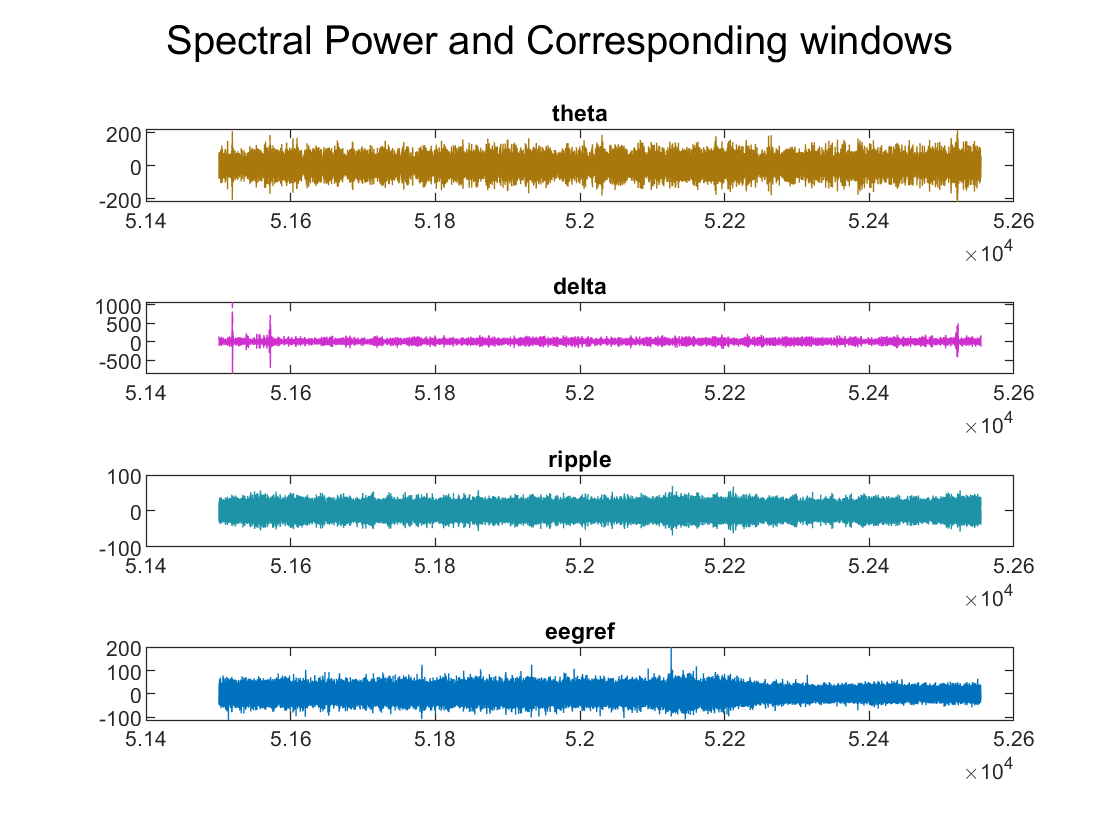

load(animal+'ripples01.mat')

[epochstart, epochend, start,stop,timeranges] = getRipStartStop(ripples);
RIPPLE=3;
plotType = 'area';
ripindices = [];

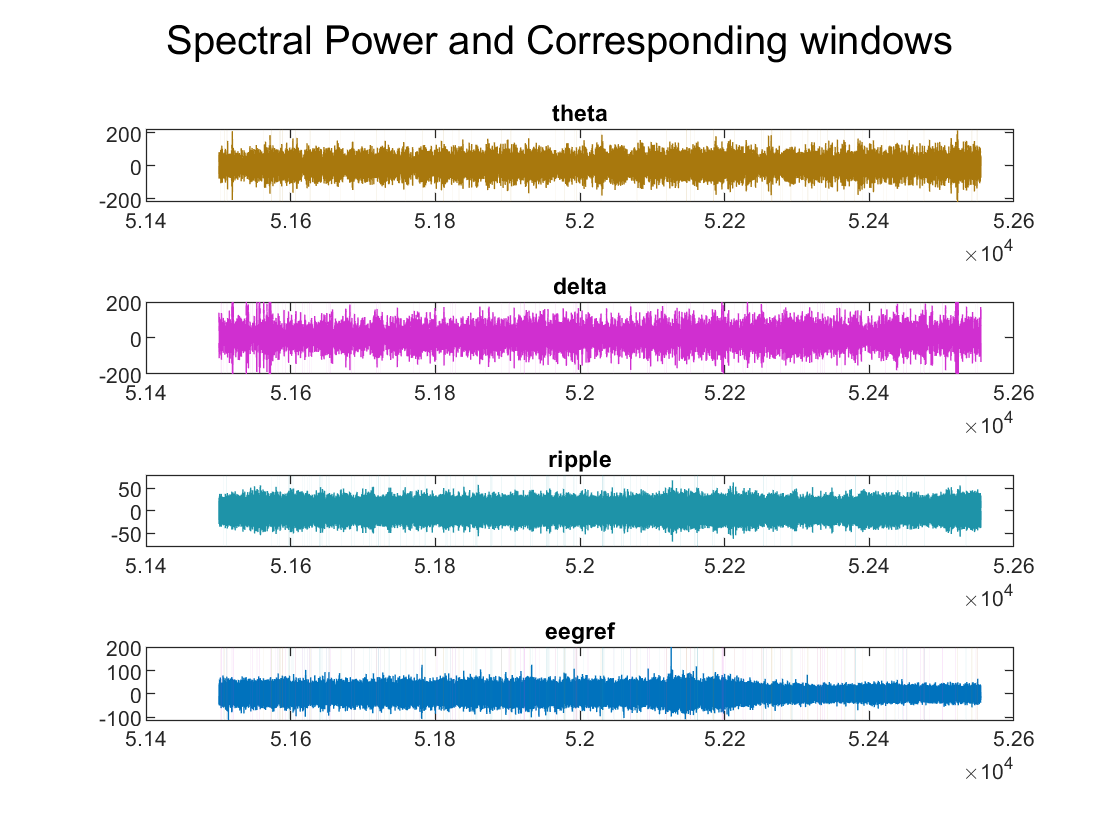


switch plotType
    case 'area'
        epsilon = 0.000000000001;
        uniqueTimePeriods = unique(timeranges,'rows');
        disp("Number unique periods = " + size(uniqueTimePeriods,1))
        % Plot H just one time
        for iTimePeriods = 1:size(uniqueTimePeriods,1)
            figure(10000 + iTimePeriods);clf
            % Start and stop of a single epoch
            epochstart = uniqueTimePeriods(iTimePeriods,1);
            epochstop  = uniqueTimePeriods(iTimePeriods,2);
            
            htimes_in_epoch = times > epochstart & times < epochstop;
            
            if sum(htimes_in_epoch) ~= 0 % there are corresponding times
                h_indices = [];
                sgtitle(sprintf('Epoch %d', iTimePeriods));
                
                subplot(2,1,1)
                plot(times(htimes_in_epoch), H(htimes_in_epoch, RIPPLE),'linewidth',2) %ripple file not aligned?
                ylimits = get(gca,'Ylim');
                hold on;
                % Get all ripples in the epoch
                ripsInPeriod = start(:,1) >= epochstart & stop(:,1) < epochstop;
                % 1 epoch worth of ripples
                startpoints = start(ripsInPeriod, 1);
                stoppoints  = stop(ripsInPeriod, 1);
                % Iterate all ripples in a single epoch
                disp(''); % print blank line
                for iRip = progress(1:numel(startpoints), ...
                        'Title', sprintf('Plotting epoch %d ripple',iTimePeriods))
                    y = [0 0 ylimits(2) ylimits(2) 0 0];
                    x = [epochstart startpoints(iRip)-epsilon startpoints(iRip) ...
                        stoppoints(iRip) stoppoints(iRip)+epsilon epochstop];
                    area(x,y,'FaceAlpha',0.60, 'FaceColor', 'black', 'EdgeColor','none');
                    curr_hindices = find(times >= startpoints(iRip) & times <= stoppoints(iRip));
                    if(iscolumn(h_indices))
                        h_indices = h_indices';
                    end
                    
                    if(iscolumn(curr_hindices))
                        curr_hindices = curr_hindices';
                    end
                    h_indices = [h_indices,curr_hindices];
                end
                
                drawnow;
                title("Ripple windows' relation with ripple power")
                
                ripple_power_in_ripples = H(h_indices, RIPPLE);
                ripple_power_not_in_ripple = H(~ismember(1:size(H,1), h_indices), RIPPLE);
                
                nonrip_mean = mean(ripple_power_not_in_ripple(~isnan(ripple_power_not_in_ripple)));
                nonrip_std = std(ripple_power_not_in_ripple(~isnan(ripple_power_not_in_ripple)));
                rip_mean = mean(ripple_power_in_ripples(~isnan(ripple_power_in_ripples)));
                rip_std = std(ripple_power_in_ripples(~isnan(ripple_power_in_ripples)));
                
                subplot(2,1,2)
                bar( [0:1],[nonrip_mean,rip_mean],0.5);

                hold on
                errorbar([0:1],[nonrip_mean,rip_mean],[nonrip_std,rip_std],'.')
                set(gca,'XTick', [0:1],'XTickLabel',["non-ripple","ripple"]);
                title("Mean power for ripple periods and non-ripple periods")
            end
            
        end
    case 'line'
        x = midtimes;
        x = [x'; x'];
        y = ylimits;
        y = repmat(y', 1, length(x));
        hold on;
        line(x,y, 'Color', 'black', 'linewidth', 2);
end

### **III. **$B$** sane (in Reduced Rank Regression)**

figure(130)
linearized = [];
for p = 1:Option.numPartition
    for j = 1:2
        for i=1:numResult
            subplot(2,3,i)
            B_ = Patterns(i).B_;
            imagesc(B_);
            cmocean('balance')
            biggest_number = max(abs(B_(:)));
            set(gca,'clim',[-biggest_number, biggest_number])
            
            title(Patterns(i).name)
            linearized = [linearized Patterns(i).B_(:)];
        end
    end
end



### IV. EEG check

load(animal + "eegref01-14-17.mat")
load(animal + "theta01-14-17.mat")
load(animal + "delta01-14-17.mat")
load(animal + "ripple01-14-17.mat")

clf;
pattern_specific = true;

eegsamp = eegref{1}{14}{17};
eegdata = eegsamp.data;
deltasamp = delta{1}{14}{17};
thetasamp = theta{1}{14}{17};
ripplesamp = ripple{1}{14}{17};

% Filtered band
deltadata = deltasamp.data(:,1);
thetadata = thetasamp.data(:,1);
rippledata = ripplesamp.data(:,1);

% Filtered amplitude (hilbert amp)
deltaAmp = deltasamp.data(:,3);
thetaAmp = thetasamp.data(:,3);
rippleAmp = ripplesamp.data(:,3);

% Normalize - RY : any reason why doing this if using separate subplots?
eegdata = double(max(thetadata)).* eegdata / max(eegdata);

data = [thetadata, deltadata, rippledata, eegdata];
amp = [thetaAmp, deltaAmp, rippleAmp];
datatitles = ["theta","delta","ripple","eegref"];
colors = cmocean('phase', 4); % only first 3 colors used for 3 patterns

figure(300), clf
timeaxis = linspace(eegsamp.starttime, eegsamp.endtime, length(eegdata));

for i = 1:4
    subplot(4,1,i)
    p(1) = plot(timeaxis,data(:,i));
    if i < 4
        hold on
        p(2) = plot(timeaxis, amp(:,i), '--');
        set(p, 'Color', colors(i,:))
    end
    title(datatitles(i));
end

sgtitle("Spectral Power and Corresponding windows")

ylimits = get(gca,'Ylim');
epsilon = 0.0001;
hold on


for iPlot = 1:4
    ax(i) = subplot(4,1,iPlot);
    
    xlim([51400,52600]);
    if (iPlot==2)
        ylim([-200,200]);
    elseif (iPlot==3)
        ylim([-80, 80]);
    end
    if ~pattern_specific || (pattern_specific && iPlot == 4)
        for i = 1:nPatterns
            curr_windows = cellOfWindows{i};
            patternstart = curr_windows(1,1);
            patternend = curr_windows(end,2);
            
            
            [graphicalObject] = windows.plot(curr_windows);
            
            if (i == RIPPLE)
                set(graphicalObject,'FaceAlpha',0.30, 'FaceColor', colors(RIPPLE,:), 'EdgeColor','none');
            elseif (i == DELTA)
                set(graphicalObject,'FaceAlpha',0.30, 'FaceColor', colors(DELTA,:), 'EdgeColor','none');
            else
                set(graphicalObject,'FaceAlpha',0.30, 'FaceColor', colors(THETA,:), 'EdgeColor','none');
            end
            
        end
        
    else % the plots are pattern-specific and we are plotting the pattern subplots (1-3)
        curr_windows = cellOfWindows{iPlot};
        patternstart = curr_windows(1,1);
        patternend = curr_windows(end,2);
        graphicalObject = windows.plot(curr_windows);
        set(graphicalObject,'FaceAlpha',0.30, 'FaceColor', colors(iPlot,:), 'EdgeColor','none');
        %
        %             if (i == RIPPLE)
        %                 set(graphicalObject,'FaceAlpha',0.40, 'FaceColor', 'black', 'EdgeColor','none');
        %             elseif (i == DELTA)
        %                 set(graphicalObject,'FaceAlpha',0.40, 'FaceColor', 'red', 'EdgeColor','none');
        %             else
        %                 set(graphicalObject,'FaceAlpha',0.40, 'FaceColor', 'blue', 'EdgeColor','none');
        %             end
        
        %         for nWindows = 1:size(curr_windows,1)
        %
        %             windowstart = curr_windows(nWindows,1);
        %             windowend = curr_windows(nWindows,2);
        %             y = [0 0 ylimits(2) ylimits(2) 0 0];
        %             x = [patternstart windowstart-epsilon windowstart ...
        %                 windowend windowend+epsilon patternend];
        %             hold on
        %             area(x,y,'FaceAlpha',0.40, 'FaceColor', 'black', 'EdgeColor','none');
        %
        %             hold on
        %         end
    end
end
linkaxes(findobj(gca,'type','axes'),'x')
